clear; clc; close all;

generatedFile = fullfile('ISC_out_with_680_820.xlsx');

resistances = [30 50 85 100 220 300 500 680 820];
refCells    = [5  5  5  6   5   5   5   5   5];
faultCell = 8;
threshold = 0.02;

series = cell(numel(resistances), 1);
sourceRows = zeros(numel(resistances), 1);

for k = 1:numel(resistances)
    sourceFile = fullfile( pwd, '..', '..', 'data',sprintf('ISC_%d.xlsx', resistances(k)));
    assert(isfile(sourceFile), 'Missing source file: %s', sourceFile);

    M = readmatrix(sourceFile);
    M = M(~all(isnan(M), 2), :);
    assert(size(M, 2) >= faultCell, ...
        'Source file %s must contain at least %d columns.', sourceFile, faultCell);

    refIncrement = M(:, refCells(k)) - M(1, refCells(k));
    faultIncrement = M(:, faultCell) - M(1, faultCell);
    dVd = refIncrement - faultIncrement;

    series{k} = dVd;
    sourceRows(k) = numel(dVd);
end

maxRows = max(sourceRows);
generated = nan(maxRows, numel(resistances));
outCell = cell(maxRows, numel(resistances));

for k = 1:numel(resistances)
    generated(1:sourceRows(k), k) = series{k};
    outCell(1:sourceRows(k), k) = num2cell(series{k});
end

writecell(outCell, generatedFile, 'Sheet', 1, 'Range', 'A1');


%% Diagnose by 20 mV threshold
firstCrossing = nan(numel(resistances), 1);
maxDeltaVd = nan(numel(resistances), 1);
diagnosis = strings(numel(resistances), 1);

for k = 1:numel(resistances)
    valid = generated(:, k);
    valid = valid(isfinite(valid));
    maxDeltaVd(k) = max(valid);

    idx = find(valid >= threshold, 1, 'first');
    if isempty(idx)
        diagnosis(k) = "Not detected";
    else
        firstCrossing(k) = idx;
        diagnosis(k) = "Detected";
    end
end

summary = table(resistances(:), refCells(:), sourceRows(:), maxDeltaVd, ...
    firstCrossing, diagnosis, ...
    'VariableNames', {'Resistance_Ohm', 'ReferenceCell', 'Rows', ...
    'MaxDeltaVd_V', 'FirstCrossing_20mV_s', 'Diagnosis_20mV'});
disp(summary);

    Resistance_Ohm    ReferenceCell    Rows    MaxDeltaVd_V    FirstCrossing_20mV_s    Diagnosis_20mV
    ______________    _____________    ____    ____________    ____________________    ______________

          30                5          3195      0.082618               486            "Detected"    
          50                5          3176      0.058032               727            "Detected"    
          85                5          3198      0.042931               967            "Detected"    
         100                6          3230       0.03185              1661            "Detected"    
         220                5          3230      0.025201              2153            "Detected"    
         300                5          3318       0.02426              2919            "Detected"    
         500                5          3331      0.021166              3229            "Detected"    
         680                5          3305      0.019609               NaN      


fprintf('Generated file: %s\n', generatedFile);

Generated file: ISC_out_with_680_820.xlsx


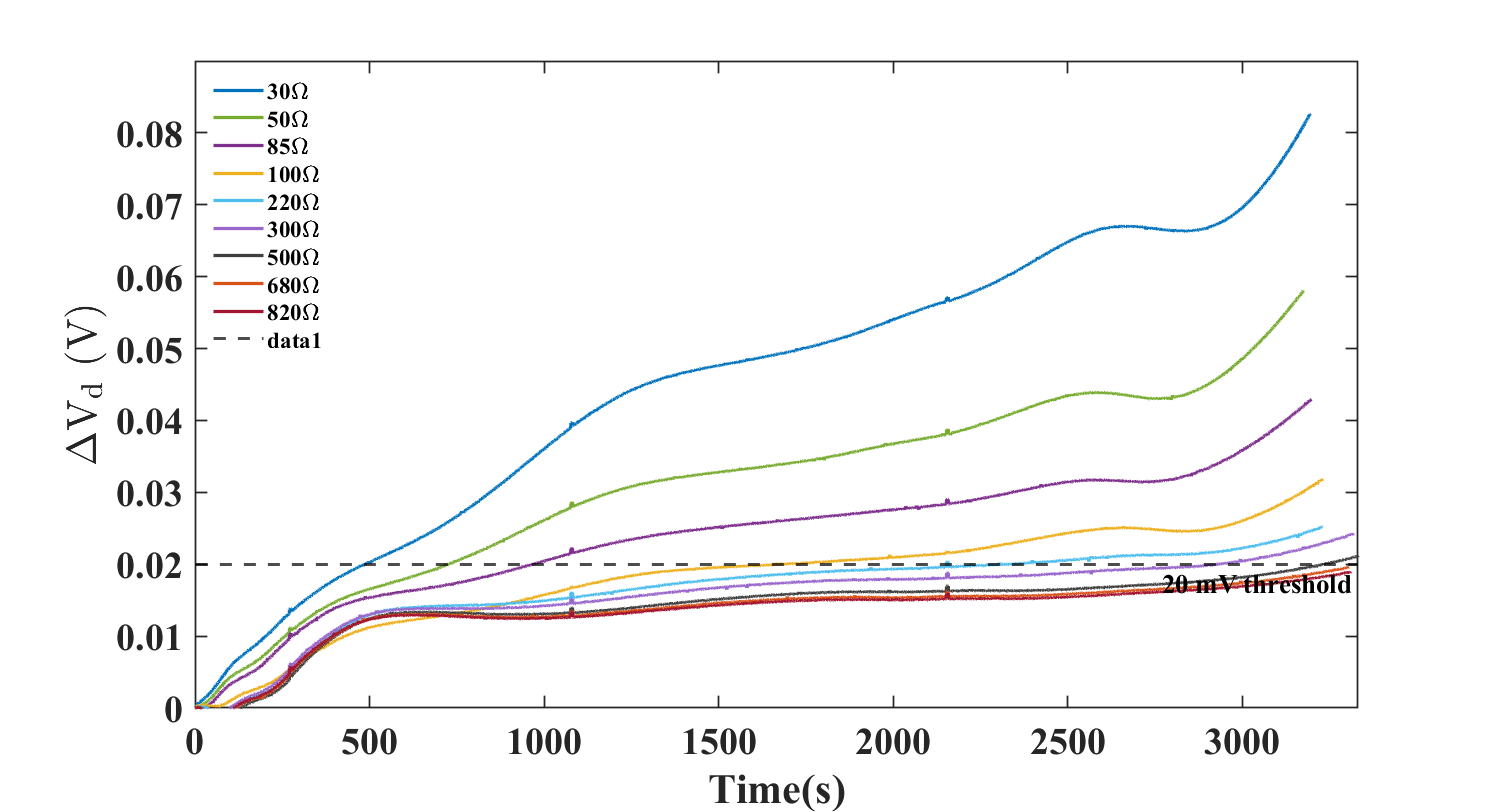


%% Plot a Fig. 8-like curve
fig = figure('Color', 'w', 'Position', [100, 100, 1200, 650]);
ax = axes(fig);
hold(ax, 'on');

colors = [ ...
    0.0000 0.4470 0.7410; ...
    0.4660 0.6740 0.1880; ...
    0.4940 0.1840 0.5560; ...
    0.9290 0.6940 0.1250; ...
    0.3010 0.7450 0.9330; ...
    0.6000 0.4000 0.8000; ...
    0.2500 0.2500 0.2500; ...
    0.8500 0.3250 0.0980; ...
    0.6350 0.0780 0.1840 ...
];

for k = 1:numel(resistances)
    t = (1:sourceRows(k))';
    plot(ax, t, series{k}, 'LineWidth', 2, ...
        'Color', colors(k, :), ...
        'DisplayName', sprintf('%d\\Omega', resistances(k)));
end

yline(ax, threshold, '--k', '20 mV threshold', ...
    'LineWidth', 1.8, ...
    'LabelHorizontalAlignment', 'right', ...
    'LabelVerticalAlignment', 'bottom', ...
    'FontName', 'Times New Roman', ...
    'FontSize', 16, ...
    'FontWeight', 'bold');

xlabel(ax, 'Time(s)', 'FontSize', 25, 'FontWeight', 'bold', 'FontName', 'Times New Roman');
ylabel(ax, '$\mathrm{\Delta V_d}$ (V)', 'FontSize', 25, 'FontWeight', 'bold', ...
    'FontName', 'Times New Roman', 'Interpreter', 'latex');

xlim(ax, [0, maxRows]);
ylim(ax, [0, 0.09]);
grid(ax, 'off');
box(ax, 'on');

set(ax, 'FontSize', 23, 'FontName', 'Times New Roman', ...
    'FontWeight', 'bold', 'LineWidth', 1);

legend(ax, 'Location', 'northwest', 'FontSize', 14, ...
    'FontName', 'Times New Roman', 'Box', 'off', 'FontWeight', 'bold');

hold(ax, 'off');